# INTERPOLACIÓ POLINOMIAL (primera part)

## APRENEM .....

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

- avalueu el polinomi  $x^5-1$ per $x=2$

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

p=[1 4 1 0]                   % vector amb els coeficients del polinomi 

p =      1     4     1     0


roots(p)                      % arrels

ans =          0
   -3.7321
   -0.2679


p=[1 0 0 0 0 -1]              % vector amb els coeficients del polinomi 

p =      1     0     0     0     0    -1


polyval(p,2)                  % valor polinomi

ans = 31

x=[-5 -2 -1 1 2 8 ]           % vector amb les arrels

x =     -5    -2    -1     1     2     8


y=[0 0 0 0 0 0]

y =      0     0     0     0     0     0


grau = length(x)-1;
p = polyfit(x,y,grau)         % coeficients polinomi d'arrels r

p =      0     0     0     0     0     0


### Polinomi interpolador

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu la pàgina 5 i reproduïu el seu exemple. 

x = 1:6

x =      1     2     3     4     5     6


y = [16 18 21 17 15 12];
disp([x; y]);

     1     2     3     4     5     6
    16    18    21    17    15    12



polyinterp(x,y,4.5)

ans = 15.3164

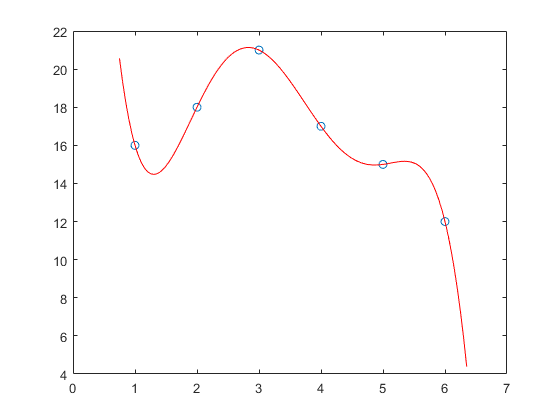

u = .75:0.05:6.35;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-');

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

Els coeficients del polinomi interpolador es poden obtenir amb polifit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

x = 1:6

x =      1     2     3     4     5     6


y = [16 18 21 17 15 12];
disp([x; y]);

     1     2     3     4     5     6
    16    18    21    17    15    12



grau = length(x)-1;
p = polyfit(x,y,grau)

p =    -0.2417    4.3333  -28.9583   87.6667 -115.8000   69.0000


polyval(p,4.5)

ans = 15.3164

polyinterp de Moler = polyfit+polyval

## PRACTIQUEM ....

### 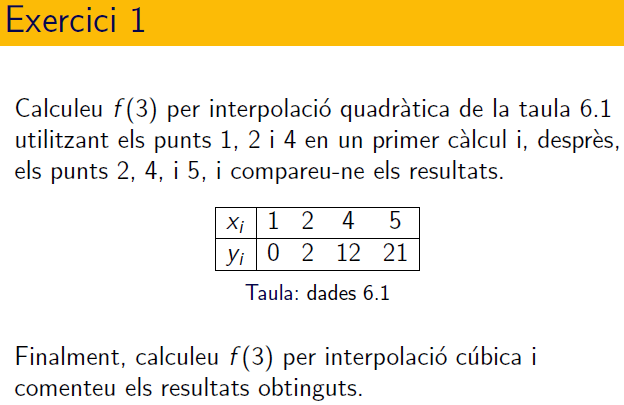

Aquest exercici s'ha de resoldre fent ús de **polyinterp**

% primer càlcul
x = [1 2 4];
y = [0 2 12];
polyinterp(x,y,3)

ans = 6

% segon  càlcul
x = [2 4 5];
y = [2 12 21];
polyinterp(x,y,3)

ans = 5.6667

% tercer  càlcul
x = [1 2 4 5];
y = [0 2 12 21];
polyinterp(x,y,3)

ans = 5.8333

### 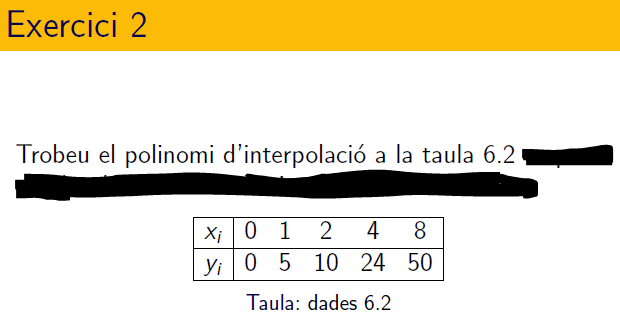

 x = [0 1 2 4 8];
 y = [0 5 10 24 50];
 grau = length(x)-1;
 polyfit(x,y,grau)

ans =    -0.0342    0.4062   -0.9792    5.6071    0.0000


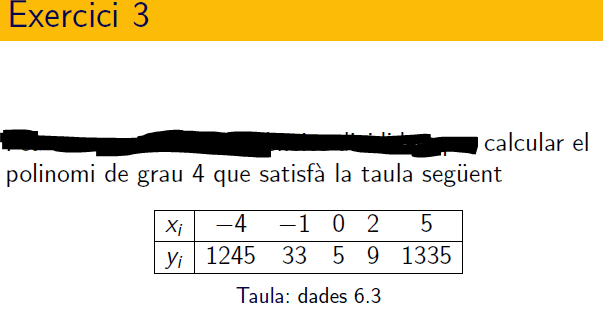

x = [-4 -1 0 2 5];
y = [1245 33 5 9 1335];
grau = 4;
polyfit(x,y,grau)

ans =     3.0000   -5.0000    6.0000  -14.0000    5.0000


## 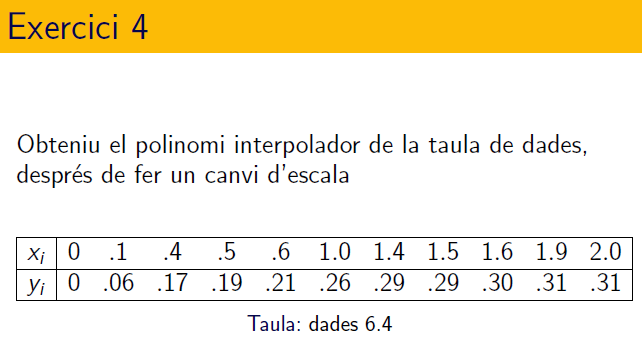

x = [0 .1 .4 .5 .6 1 1.4 1.5 1.6 1.9 2.0]

x =          0    0.1000    0.4000    0.5000    0.6000    1.0000    1.4000    1.5000    1.6000    1.9000    2.0000


y = [0 0.06 .17 .19 .21 .26 .29 .29 .39 .31 .31]

y =          0    0.0600    0.1700    0.1900    0.2100    0.2600    0.2900    0.2900    0.3900    0.3100    0.3100


[p, ~, mu] = polyfit(x,y,grau)

p =    -0.0463    0.0105    0.0381    0.0895    0.2501


mu =     1.0000
    0.7183


f = polyval(p,4.5,[], mu)

f = -23.2826

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. 

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

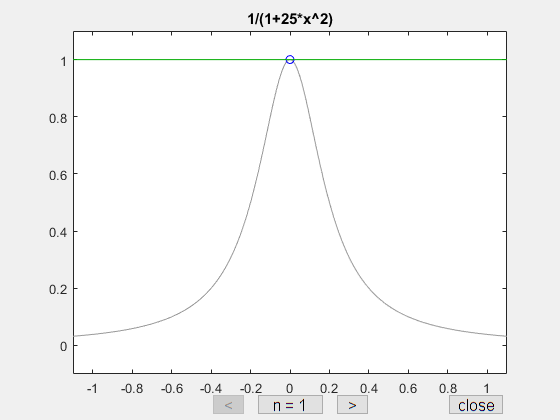

rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

% interp_gadget()

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

clear figure
x = 1:6

x =      1     2     3     4     5     6


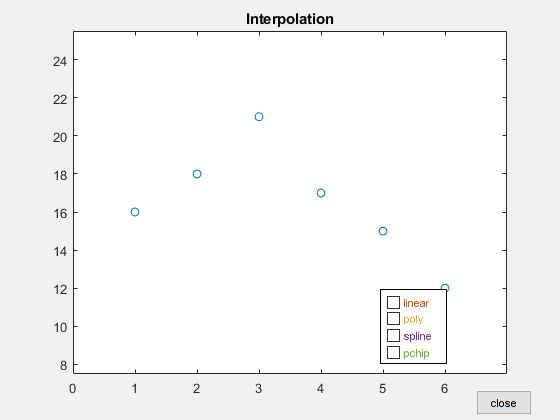

y = [16 18 21 17 15 12];
interpgui(x,y)